# Lab 2

addpath('../LabFiles/Functions/')
addpath('../LabFiles/Images-m/')

## 1  Difference operators

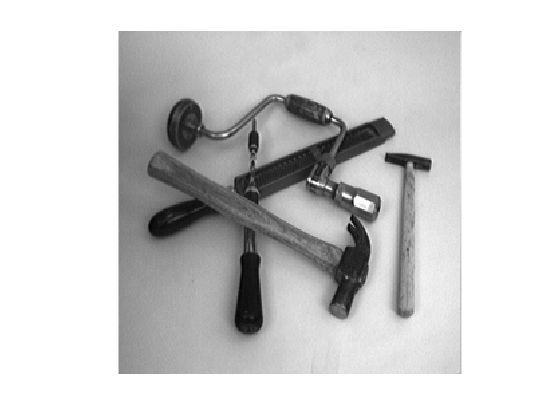

deltax = 0.5*[-1,0,1];
deltay = 0.5*[-1;0;1];

tools = few256;
showgrey(tools);

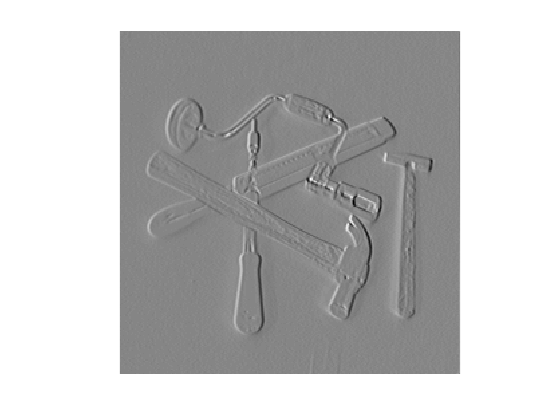

dxtools = conv2(tools, deltax, 'valid');
showgrey(dxtools);

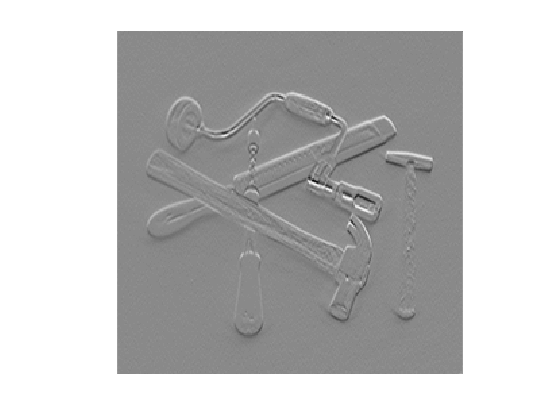

dytools = conv2(tools, deltay, 'valid');
showgrey(dytools)

## 2  Point–wise thresholding of gradient magnitudes

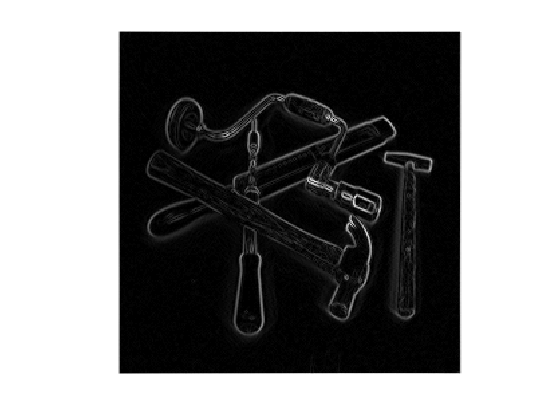

dxtools = conv2(tools, deltax, 'same');
dytools = conv2(tools, deltay, 'same');

gradmagntools = sqrt(dxtools .^2 + dytools .^2);
showgrey(gradmagntools)

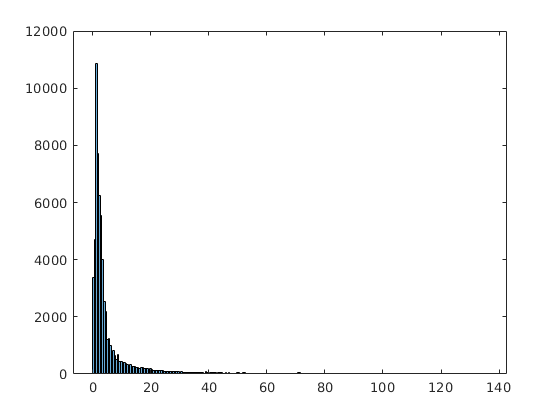

histogram(gradmagntools,256);

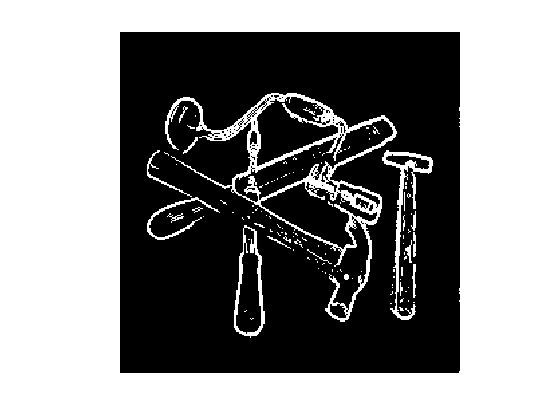

%set(gca, 'YScale', 'log')

showgrey((gradmagntools - 18) > 0)

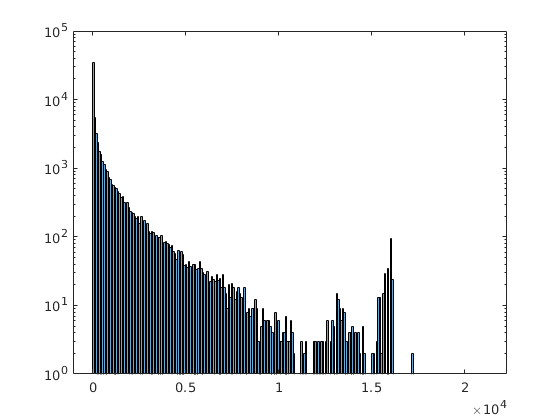

img = godthem256;
M = Lv(img);


histogram(M,256);
set(gca, 'YScale', 'log')

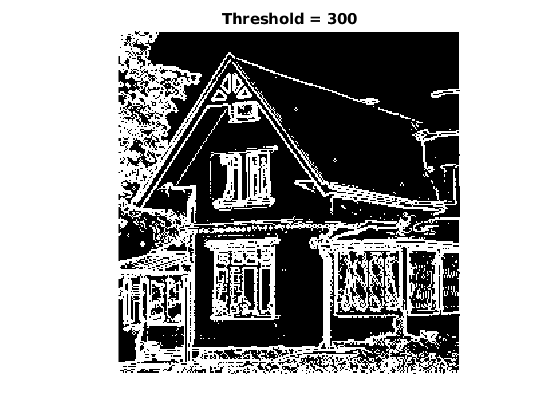

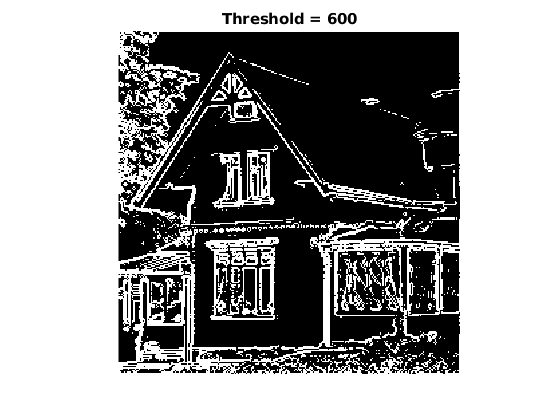

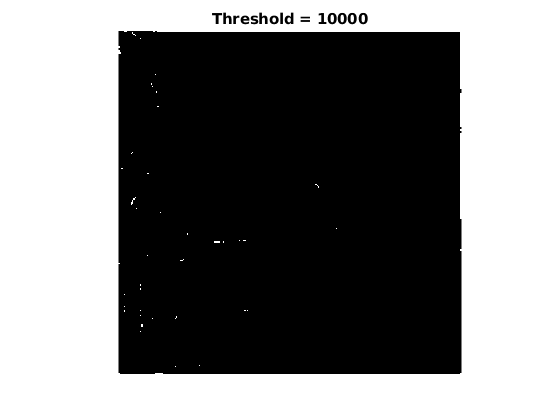


for threshold = [300,600,10000]
    figure();
    showgrey((Lv(img) - threshold) > 0)
    title(sprintf("Threshold = %g",threshold))
end

with smoothing

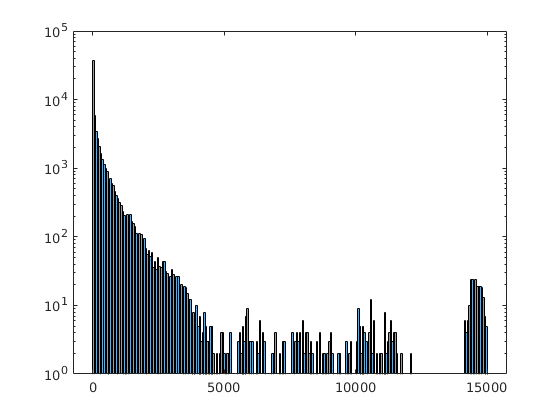

img = discgaussfft(godthem256,1);
M = Lv(img);


histogram(M,256);
set(gca, 'YScale', 'log')

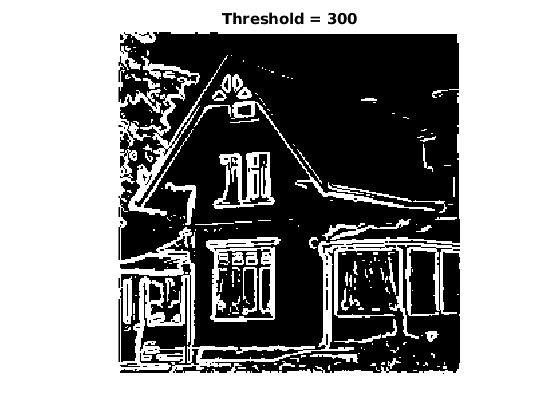

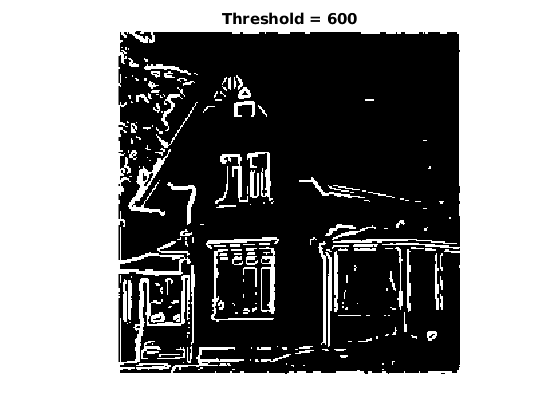

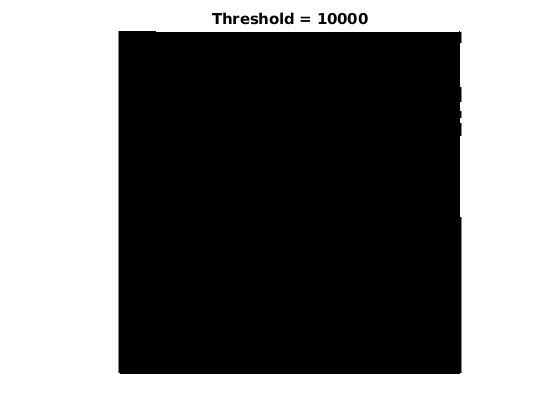


for threshold = [300,600,10000]
    figure();
    showgrey((Lv(img) - threshold) > 0)
    title(sprintf("Threshold = %g",threshold))
end

## 4  Computing differential geometry descriptors

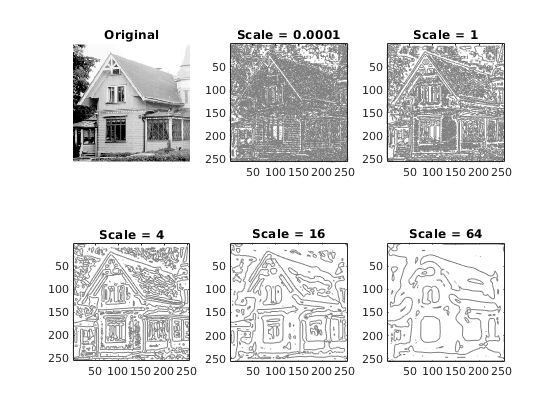

house = godthem256;
figure();

subplot(2,3,1);
showgrey(house);
title("Original")

idx = 2;
for scale = [0.0001 1.0 4.0 16.0 64.0]
    subplot(2,3,idx);
    contour(Lvvtilde(discgaussfft(house, scale )), [0 0]);
    title(sprintf("Scale = %g", scale));
    axis('image')
    axis('ij')
    idx = idx + 1;
end

saveas(gcf,'question4.svg')

Now let's see the third derivative

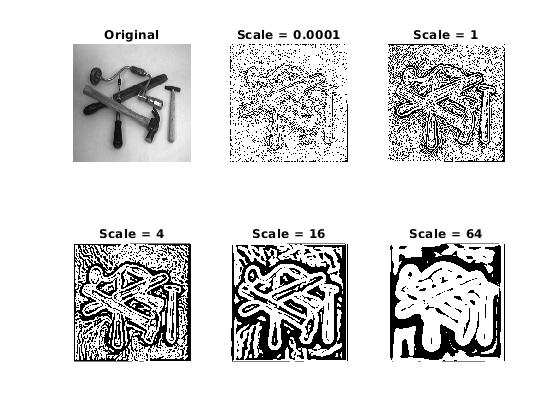

figure('DefaultAxesPosition', [0.1, 0.1, 0.8, 0.8]);
tools = few256;
subplot(2,3,1);
showgrey(tools);
title("Original");

idx = 2;
for scale = [0.0001 1.0 4.0 16.0 64.0]
    h = subplot(2,3,idx);
    showgrey(Lvvvtilde(discgaussfft(tools, scale)) < 0)
    title(sprintf("Scale = %g", scale));
    axis('image');
    axis('ij');
    idx = idx + 1;
end

saveas(gcf,'question5.svg')

## 5  Extraction of edge segments

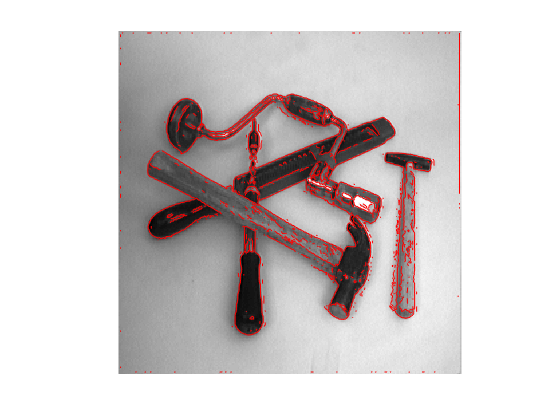

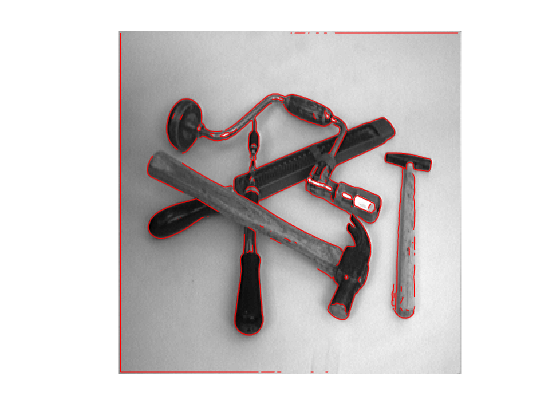

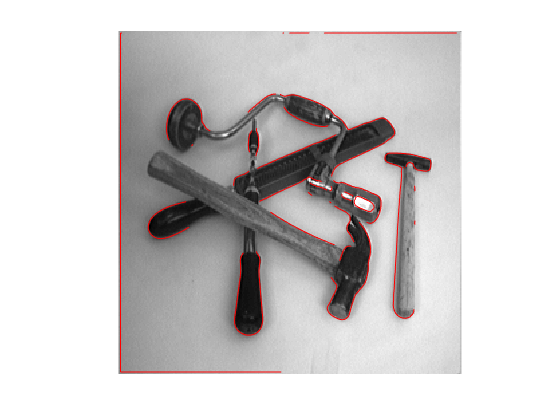

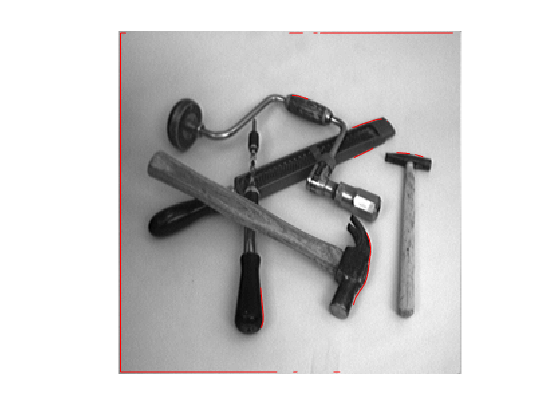

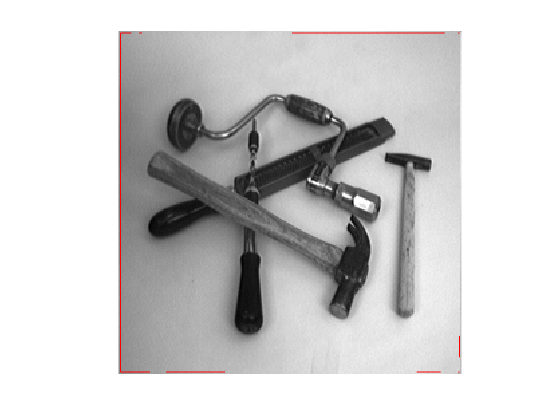

tools = few256;
house = godthem256;

warning ('off','all');
for scale = [0.0001 1.0 4.0 16.0 64.0]
    figure();
    curves = extractedge(tools,scale, 200, 'same');
    overlaycurves(tools, curves);

end

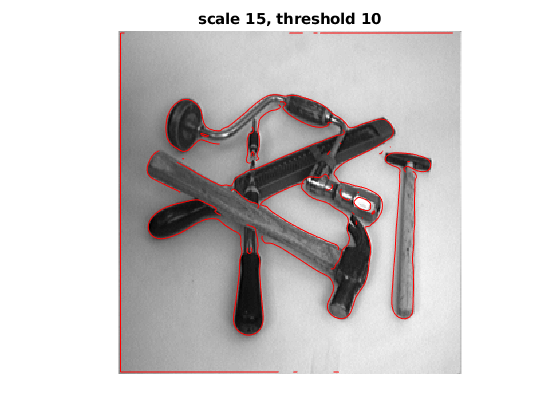

warning ('off','all');
figure();
scale = 15;
threshold = 10;
curves = extractedge(tools,scale, threshold, 'same');
overlaycurves(tools, curves);
title(sprintf("scale %g, threshold %g", scale, threshold));

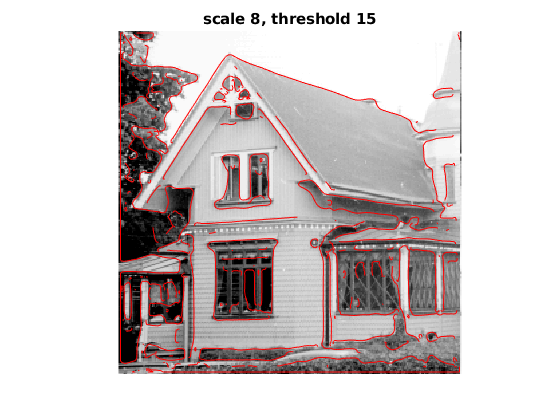


figure();
scale = 8;
threshold = 15;
curves = extractedge(house,scale, threshold, 'same');
overlaycurves(house, curves);
title(sprintf("scale %g, threshold %g", scale, threshold));

## 6  Hough transform

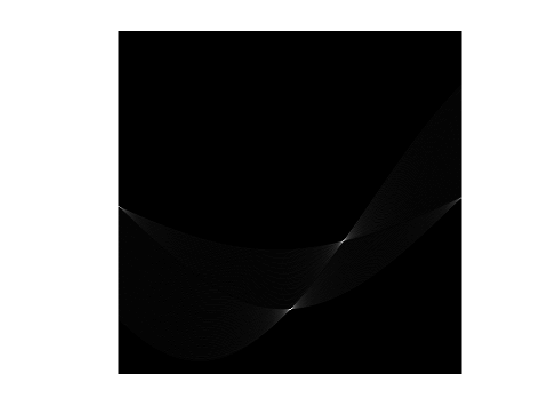

Image size is 128drho 1.21739 	 dtheta 0.6

%warning ('off','all');
testimage1 = triangle128;

smalltest1 = binsubsample(testimage1);

figure();

nlines = 3;
[a,b] = houghedgeline(testimage1,1,10,300,300,nlines,true);

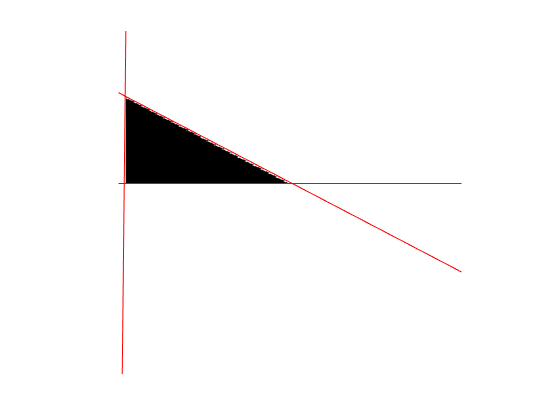

overlaycurves(testimage1, a);

axis([0 256 0 256])

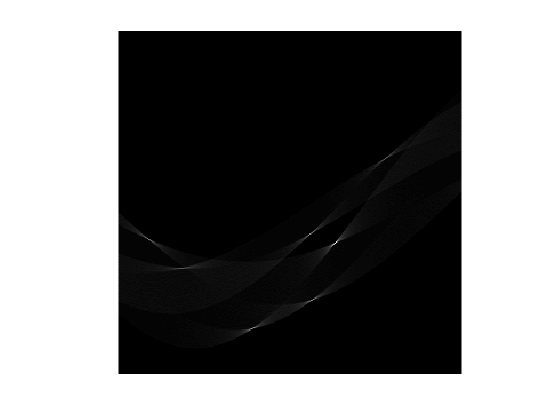

Image size is 256drho 2.42809 	 dtheta 0.6


figure();
testimage1 = houghtest256;

nlines = 7;
[a,b] = houghedgeline(testimage1,1,10,300,300,nlines,true);

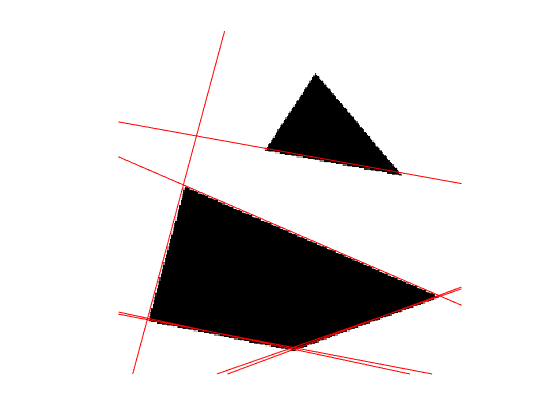

overlaycurves(testimage1, a);

axis([0 256 0 256])

% edges =zeros(2,4*nlines);
% for i = 1 : nlines
%     
%     rho = a(i,1);
%     theta = a(i,2);
% 
%     x0 = (rho)*cos(theta);
%     y0 = (rho)*sind(theta);
%     dy = 1000 * cosd(theta) ;
%     %dx = - dy * sind(theta)/cosd(theta);
%     dx = - 1000 *  sind(theta);
% 
%     edges(1, 4*(i-1) + 1) = 0; % level, not significant
%     edges(2, 4*(i-1) + 1) = 3; % number of points in the curve
%     edges(1, 4*(i-1) + 2) = x0-dx;
%     edges(2, 4*(i-1) + 2) = y0-dy;
%     edges(1, 4*(i-1) + 3) = x0;
%     edges(2, 4*(i-1) + 3) = y0;
%     edges(1, 4*(i-1) + 4) = x0+dx;
%     edges(2, 4*(i-1) + 4) = y0+dy;
% end
% 
% 
% overlaycurves(testimage1, edges);